# PI Design with Root Locus

Design constraints.  Translate from second-order metrics to s-plane geometry.

close('all')
Tr = 0.9;
omega_n = 1.8/Tr

omega_n = 2

os = 2;
zeta = -log(os/100) / sqrt(pi^2 + log(os/100)^2)

zeta = 0.7797

- 
$$T_r \le 0.9 \: \text{s} \rightarrow \omega_n \ge 2.0 \: \text{rad/s$$


- 
$$\zeta \ge 0.78$$


Plot the root locus for three different designs.

G = zpk([],[-5, -5, -8],1);

I did this as a loop, but can do each manually if desired.

figure(1);
clf();
pizeros = [-1 -4 -7]

pizeros =     -1    -4    -7


lspecs = ["r", "b", "g"]

lspecs = 1×3 string array
    "r"    "b"    "g"


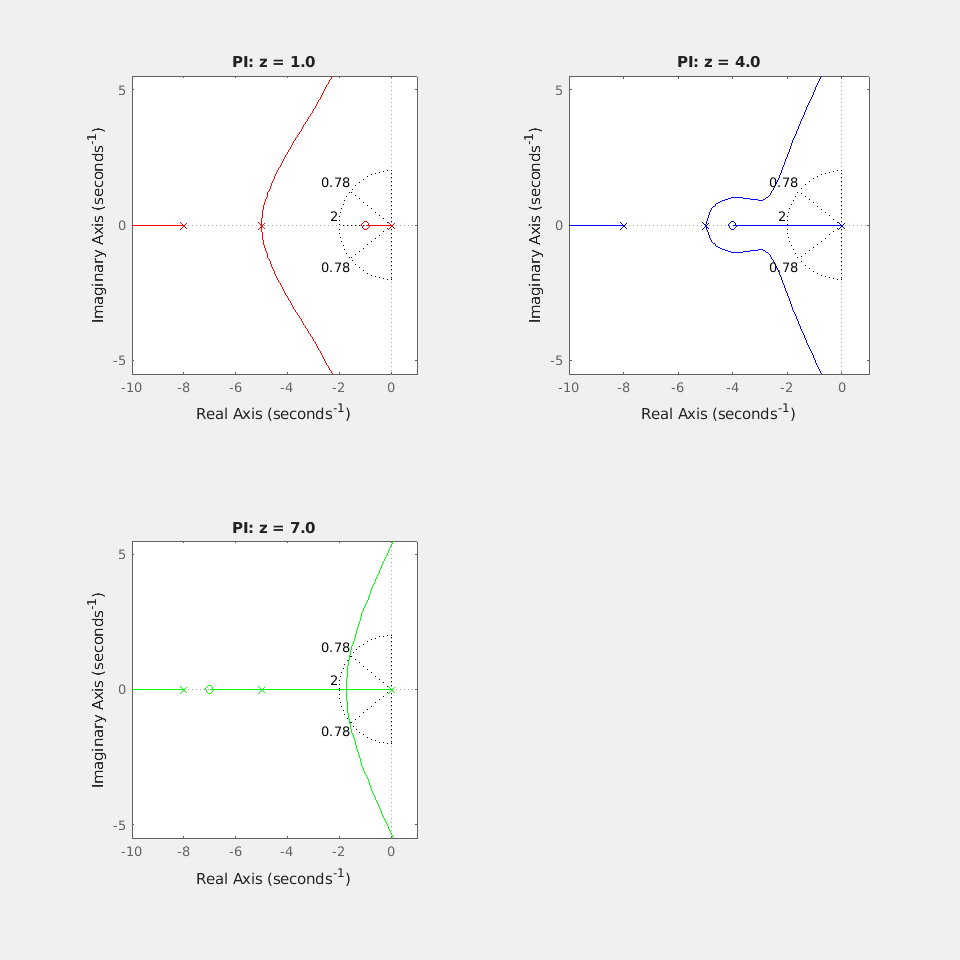

for ii = 1:length(pizeros)
    subplot(2,2,ii)
    pizero = pizeros(ii);
    D = zpk([pizero],[0],1);  
    L = D * G;
    rlocusplot(L, lspecs(ii))
    title(sprintf("PI: z = %.1f",-pizero))
    sgrid(zeta, omega_n);
    % Details to generate plots
    ax = gca;
    ax.AxesStyle.GridColor = [0 0 0];
    set(gcf,'Visible','on')
    axis([-10, 1, -5.5, 5.5])
    set(gcf,'position',[100, 100 , 960, 960])
end

The interactive plot and sgrid commands are a bit unreliable in the live-script.  You should see somethign like this...

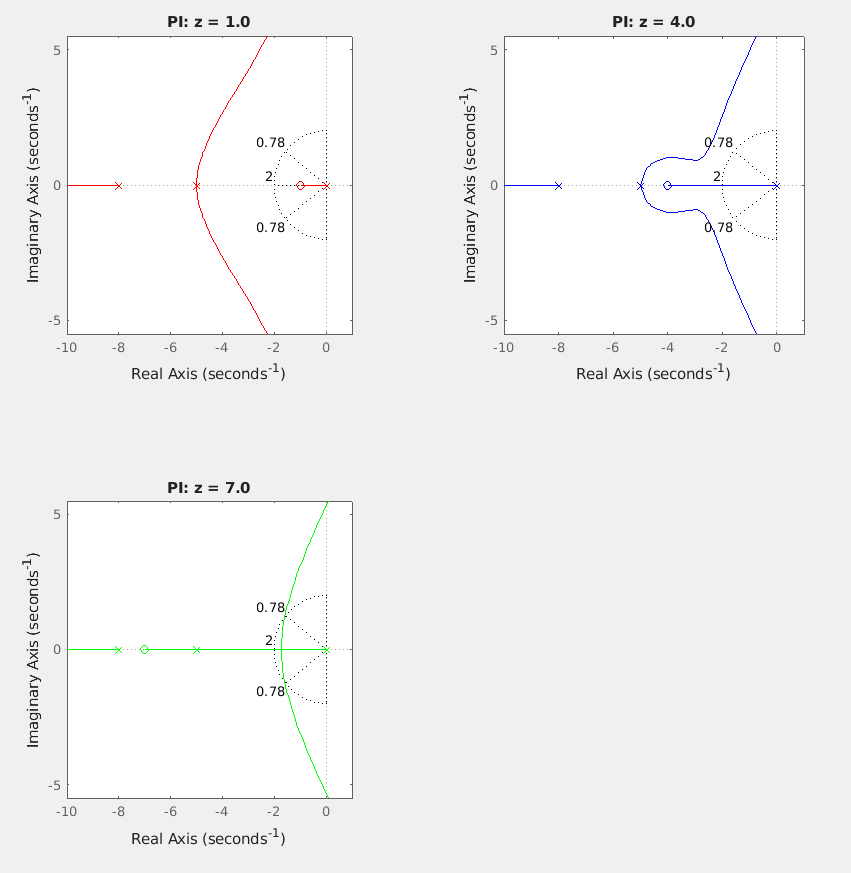

Replot just the for $z = 4$design, appears to be the only design that satisfies our constrains for $\zeta$and $\omega_n$.

Plot the root locus for this design.

pizero = %?;

Invalid expression. Check for missing or extra characters.

D = zpk([pizero],[0],1);  
L = D * G;
figure(2);
clf();
rlocus(L)
sgrid(zeta, [omega_n, 4]);
axis([-10, 1, -5.5, 5.5])

set(gcf,'Visible','on')

Use the interactive tool to choose a gain value that should satisfy the constraints.

K = %?

Overlay the predicted closed-loop pole locations

hold on
rlocus(L, K, "rs")

Close the loop and report the results.

T = feedback(K*L, 1);
damp(T)
s=stepinfo(T)
[pp, zz] = pzmap(T)
figure(3);
clf()
step(T)
title(sprintf("Step Response: %%OS = %.1f, Tr =%.2f s", s.Overshoot, s.RiseTime ))